cp_max = C_p_opt

cp_max = 0.4890

rho = 1.2225;
% R_WTR = 1
% P_mppt_sl = 0.5*pi*rho*R_WTR^5*cp_max/lambda_opt^3*omega_WTR_sl^3 %
% P_mppt_max = 15e6;0.5*pi*rho*R_WTR^5*cp_max/lambda_opt^3*omega_WTR_n^3

P_mppt_sl = 0.5*pi*rho*R_WTR*cp_max*v_w_wrated^3 %

P_mppt_sl = 1.1977e+05

P_mppt_max = 0.5*pi*rho*R_WTR*cp_max*v_w_n^3 %0.5*pi*rho*R_WTR^5*cp_max/lambda_opt^3*omega_WTR_n^3

P_mppt_max = 1.3048e+05


slope = (P_mppt_max-P_mppt_sl)/(omega_WTR_n*1.0236-omega_WTR_n)

slope = 5.7340e+05

b = P_mppt_max-slope*omega_WTR_n*1.0235

b = -3.3413e+05


omega_WTR = linspace(0.5,1.2,1000); %*2*pi/60; % rad/s
wind_speed = linspace(v_w_min-1,v_w_max+1,1000)

wind_speed =     2.0000    2.0240    2.0480    2.0721    2.0961    2.1201    2.1441    2.1682    2.1922    2.2162    2.2402    2.2643    2.2883    2.3123    2.3363    2.3604    2.3844    2.4084    2.4324    2.4565    2.4805    2.5045    2.5285    2.5526    2.5766    2.6006    2.6246    2.6486    2.6727    2.6967    2.7207    2.7447    2.7688    2.7928    2.8168    2.8408    2.8649    2.8889    2.9129    2.9369    2.9610    2.9850    3.0090    3.0330    3.0571    3.0811    3.1051    3.1291    3.1532    3.1772


TS_new = omega_WTR*R_WTR/lambda_opt

TS_new =     6.5000    6.5091    6.5182    6.5273    6.5364    6.5455    6.5547    6.5638    6.5729    6.5820    6.5911    6.6002    6.6093    6.6184    6.6275    6.6366    6.6457    6.6549    6.6640    6.6731    6.6822    6.6913    6.7004    6.7095    6.7186    6.7277    6.7368    6.7459    6.7551    6.7642    6.7733    6.7824    6.7915    6.8006    6.8097    6.8188    6.8279    6.8370    6.8461    6.8553    6.8644    6.8735    6.8826    6.8917    6.9008    6.9099    6.9190    6.9281    6.9372    6.9463



Cp_new = interp1(TSRvector,Powercoefficient(:,6),TS_new,"pchip")

Cp_new =     0.4041    0.4047    0.4053    0.4058    0.4064    0.4069    0.4075    0.4080    0.4086    0.4091    0.4097    0.4102    0.4108    0.4113    0.4118    0.4124    0.4129    0.4134    0.4140    0.4145    0.4150    0.4155    0.4161    0.4166    0.4171    0.4176    0.4181    0.4186    0.4191    0.4196    0.4201    0.4206    0.4211    0.4216    0.4221    0.4226    0.4230    0.4235    0.4240    0.4245    0.4249    0.4254    0.4259    0.4263    0.4268    0.4273    0.4277    0.4282    0.4286    0.4290


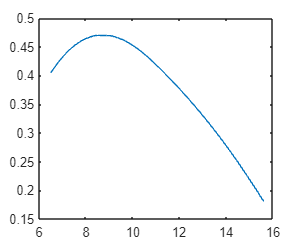

plot(TS_new,Cp_new)



y = zeros(size(omega_WTR));
y2 = zeros(size(wind_speed));

for i = 1:length(y)
    if omega_WTR(i) < omega_WTR_min
        y(i) = 0;
    elseif omega_WTR(i) < omega_WTR_sl
        y(i) = 0.5*pi*rho*R_WTR^5*cp_max/lambda_opt^3*omega_WTR(i)^3;
    elseif omega_WTR(i) < omega_WTR_n
        y(i) = slope*omega_WTR(i)+b;
        % omega_WTR_n*1.0236*R_WTR/v_w_n;
        % lambda_not_opt = 15;%TSRvector(15)
        % cp_zero_deg = Powercoefficient(15,6);
        % y(i) = 0.5*pi*rho*R_WTR^5*0.4695/8.722^3*omega_WTR(i)^3;
    else
        y(i) = 15e6;%0.5*pi*rho*R_WTR^2*cp_max*v_w_n^3;
         % y(i) = slope*omega_WTR(i)+b;
    end
    if wind_speed(i) <v_w_min
        y2(i)=0;
    elseif wind_speed(i) <v_w_n
        y2(i) = 0.5*pi*rho*R_WTR^2*cp_max*wind_speed(i)^3;
    elseif wind_speed(i) < v_w_max
        y2(i) = 15e6;
    else
        y2(i) = 0;
    end
end
omega_WTR(find(y>15e6,1))


ans =

  1×0 empty double row vector



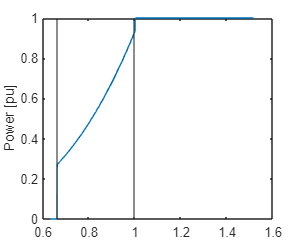

plot(omega_WTR/omega_WTR_n,y/15e6)
hold on
% plot(wind_speed/v_w_wrated, y2/15e6)
xline(omega_WTR_min/omega_WTR_n)
xline(omega_WTR_n/omega_WTR_n)
hold off
ylabel('Power [pu]')

% xlabel('Rotor rotational speed [pu]')

## CP

Powercoefficient

Powercoefficient =     0.0073    0.0094    0.0115    0.0138    0.0160    0.0184    0.0207    0.0232    0.0256    0.0281    0.0307    0.0332    0.0357    0.0383    0.0407    0.0432    0.0456    0.0478    0.0499    0.0519    0.0537    0.0552    0.0565    0.0575    0.0582    0.0585    0.0585    0.0582    0.0575    0.0565    0.0551    0.0534    0.0514    0.0491    0.0465    0.0437
    0.0194    0.0235    0.0276    0.0317    0.0359    0.0401    0.0443    0.0485    0.0527    0.0567    0.0607    0.0646    0.0682    0.0716    0.0747    0.0775    0.0798    0.0817    0.0831    0.0840    0.0843    0.0841    0.0832    0.0818    0.0799    0.0774    0.0745    0.0710    0.0672    0.0631    0.0586    0.0538    0.0488    0.0435    0.0380    0.0324
    0.0409    0.0474    0.0539    0.0603    0.0667    0.0730    0.0791    0.0850    0.0907    0.0959    0.1007    0.1050    0.1086    0.1115    0.1137    0.1150    0.1155    0.1151    0.1137    0.1116    0.1086    0.1048    0.1004    0.0953    0.0898    0.083

Pitchanglevector

Pitchanglevector =     -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


TSRvector

TSRvector =     2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000


plotTitle = "cp_tsr_6angles"

plotTitle = "cp_tsr_6angles"

figName = plotTitle;
figure('Name','Voltages'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 6.5])
legendinput = string.empty(0,6); j = 0;
for i = 6:11
    j = j+ 1
    plot(TSRvector,Powercoefficient(:,i),"LineWidth",1)
    hold on
    name = "\beta = " + string(Pitchanglevector(i)) + "^\circ";
    legendinput(j) = name;
end

j = 1

j = 2

j = 3

j = 4

j = 5

j = 6

hold off
grid on
box on
ylim([0 0.5])
xlim([2 14.5])
legendinput

legendinput = 1×6 string array
    "\beta = 0^\circ"    "\beta = 1^\circ"    "\beta = 2^\circ"    "\beta = 3^\circ"    "\beta = 4^\circ"    "\beta = 5^\circ"


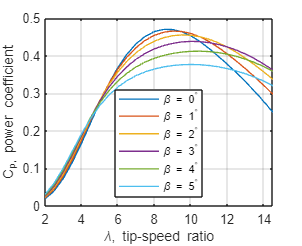

legend(legendinput,Location="south")
xlabel('\lambda, tip-speed ratio')
ylabel('C_p, power coefficient')

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 6.5])
plot_file_name = figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name =  figName +".pdf";
exportgraphics(gcf,plot_file_name)